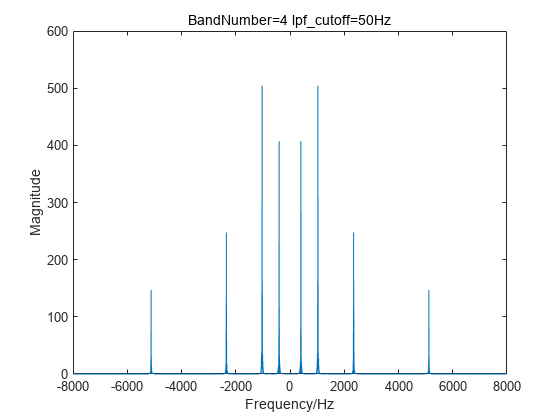

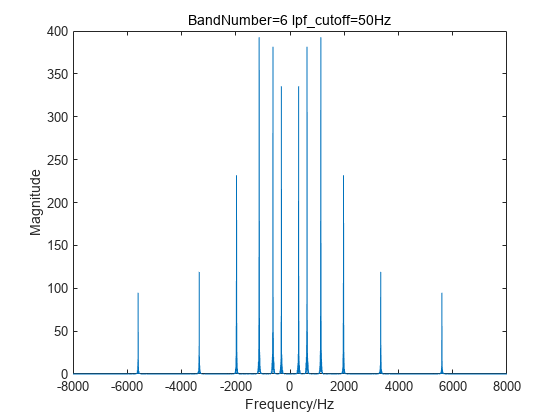

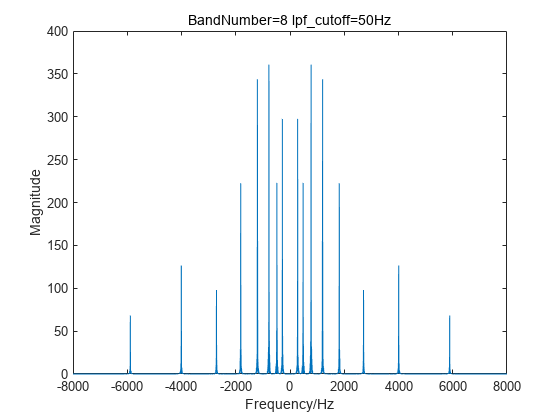

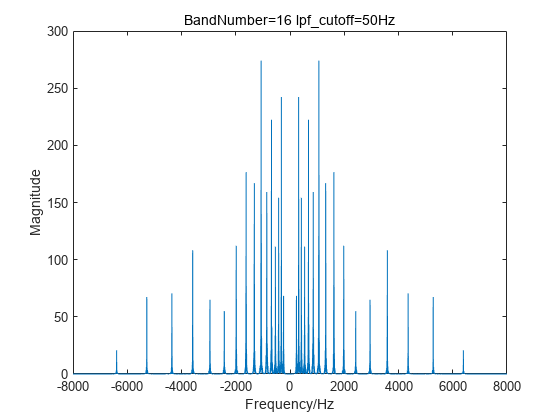

ctof_fq = 50;
[sig, fs] = audioread('C_01_02.wav');
N = [4 6 8 16];
fbe = 200; 
fen = 7000; 

% tone_vocoder(sig, n_bands, ctof_fq, but_order, fs, fbe, fen)

for i=1:length(N)
    sig_rebuild = tone_vocoder(sig, N(i), ctof_fq, 4, fs, fbe, fen);
    sig_rebuild_fft = fftshift(fft(sig_rebuild)); 
    sig_rebuild_fft_abs = abs(sig_rebuild_fft);
    f=linspace(-fs/2,fs/2,length(sig));
    figure_task1 = figure;
    plot(f,sig_rebuild_fft_abs); %Plot the figure
    title(sprintf('BandNumber=%d lpf\\_cutoff=50Hz',N(i)));
    xlabel('Frequency/Hz');ylabel('Magnitude');
    audiowrite(sprintf('./audio_out/task1/task1_N_%d_ctof_50Hz.wav',N(i)),sig_rebuild,fs);
    saveas(figure_task1,sprintf('./fig_out/task1/task1_ctof_50Hz_BandNumber_%d.jpg',N(i)));
end